# Fundamentals of GPS - Homework 3

### Tanner Koza

## Problem 1

This problem is to look at noise models.

### Find: 

- **Part A: **Show that the error from the sum **OR** difference of two independent random measurements created from $y=3a\pm4b$, where $a$ and $b$ are both zero mean with variance $\sigma_{a}^2$ and $\sigma_{b}^2$ results in:


$$\sigma_y = \sqrt{9\sigma_{a}^2 + 16\sigma_{b}^2}$$


            Perform 1000 run monte-carlo simulation to verify results.

- **Part B: **Perform a 1000 run monte-carlo simulation (of 10 minutes) to look at the error growth of a random walk (integrated white noise). Use a white noise with 1-sigma value of 0.1 and 0.01 and compare the results. Plot the mean and standard deviation of the monte-carlo simulation along with one run of the simulation (show that the random walk is zero mean with a standard deviation is $\sigma_{\int w} = \sigma_w\Delta t\sqrt{k} = \sigma_w\sqrt{t\times\Delta t}$ (where $k$ is sample number).

- **Part C: **Perform a 1000 monte-carlo simulation to look at the error growth of a 1st order markov process (integrated filtered noise) of the form $\dot{x}=-\frac{1}{\tau} x+1$. Use the same noise characteristics as above and compare the results with a 1 second and 100 second time constant (this results in 4 combinations). Comment on how changing the time constant and changing the standard deviation of the noise effects the error. Show that the 1st order markov process is zero mean with a standard deviation of is $\sigma_x = \sigma_w \Delta t \sqrt{(\frac{A^{2t}-1}{A^2-1})}$ where $A=(1-\frac{\Delta t}{\tau})$. Note that for a positive time constant (i.e. stable system) the standard deviation has a steady state value.

### Solution: 

- **Part A: **The following code runs a monte-carlo simulation for the sum and difference of two scaled random variables, $a$ and $b$. $a$'s variance was chosen to be 10 and $b$'s was chosen to be 25. Calculating $\sigma_y$ based on the equation above yields a standard deviation of $\sigma_y = 22.1359$. Therefore, it is expected the standard deviation of the sum and difference of the scaled random variables will be relatively the same. 1000 simulations were ran where the scaled random variables were summed and differenced. Then, the standard deviation was empirically calculated using the std() function in MATLAB. The results were as follows:


$$\sigma_{ysum} = 22.5623$$



$$\sigma_{ydiff} = 22.1797$$


            The results depict standard deviations that were relatively close and with an increased number of simulations will converge to the analytical value. For example, a 1000000 simulation monte-carlo yields the following:


$$\sigma_{ysum} = 22.1415$$



$$\sigma_{ydiff} = 22.1316$$


numMeas = 1;
numSims = 1000;

var_a = 10;
var_b = 25;

sigma_a = sqrt(var_a);
sigma_b = sqrt(var_b);
sigma_y = sqrt( (9 * var_a) + (16 * var_b) );

ysum = zeros(numSims, 1); % preallocation
ydiff = zeros(numSims, 1);

for j = 1:numSims
    a = sigma_a * randn(numMeas, 1);
    b = sigma_b * randn(numMeas, 1);
    
    ysum(j) = ( 3 .* a ) + ( 4 .* b );

    ydiff(j) = ( 3 .* a ) - ( 4 .* b );
end

mean_ysum = mean(ysum);
mean_ydiff = mean(ydiff);

sigma_ysum = std(ysum);
sigma_ydiff = std(ydiff);

clearvars

- **Part B: **The following plots show the mean & standard deviation of the integrated white noise ($\sigma_w=0.1$ and $\sigma_w=0.01$) along with the 1000 monte-carlo random walk simulations. The standard deviation plots depict the standard deviation of the random walk increases with the analytical solution over time as expected. This is expected because looking at the individual runs themselves shows greater dispersion about the mean as time increases. The mean for the simulations over time is relatively close to zero. The fact that it isn't closer is likely a result of the number of simulations. It can be assumed the mean will converge to 0 as the number of simulations increase.

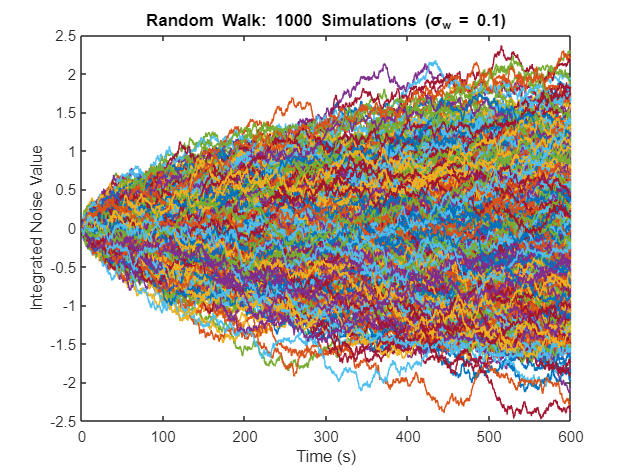

numSims = 1000;

dt = 0.1; 
t_end = 600; % end time (s)
t = 0:dt:t_end;
Ts = length(t);

sigma1 = 0.1;
sigma2 = 0.01;

wn1 = 0;
wn2 = 0;

int_wn1 = zeros(Ts, numSims); % preallocation
int_wn2 = zeros(Ts, numSims);

m_int_wn1 = zeros(numSims, 1);
m_int_wn2 = zeros(numSims, 1);

for i = 1:numSims
    
    noise1 = sigma1 * randn(Ts,1); % unit/s
    noise2 = sigma2 * randn(Ts,1); % unit/s
    
    for j = 1:Ts
        wn1 = wn1 + noise1(j)  * dt;
        wn2 = wn2 +  noise2(j)  * dt;
        
        int_wn1(j,i) = wn1;
        int_wn2(j,i) = wn2;
    end
    wn1 = 0;
    wn2 = 0;
end

mean_wn1 = mean(int_wn1,2);
mean_wn2 = mean(int_wn2,2);

std_wn1 = std(int_wn1, 0, 2);
std_wn2 = std(int_wn2, 0, 2);

an_std_wn1 = sigma1 .* sqrt(dt .* t);
an_std_wn2 = sigma2 .* sqrt(dt .* t);


figure
plot(t,int_wn1)
title('Random Walk: 1000 Simulations (\sigma_w = 0.1)')
xlabel('Time (s)')
ylabel('Integrated Noise Value')

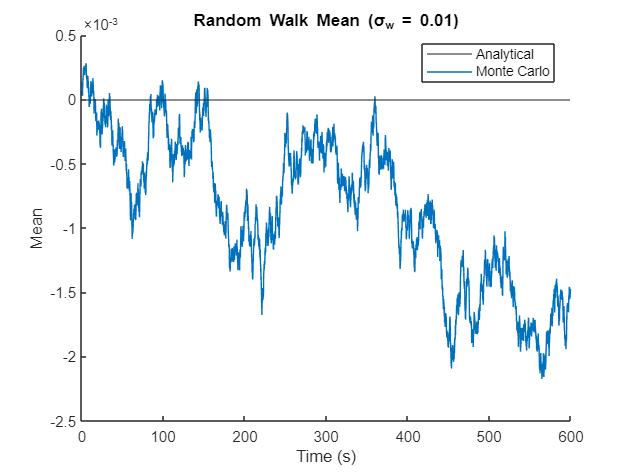


figure
yline(0)
hold on
plot(t,mean_wn2)
title('Random Walk Mean (\sigma_w = 0.01)')
xlabel('Time (s)')
ylabel('Mean')
legend('Analytical','Monte Carlo','Location','best')

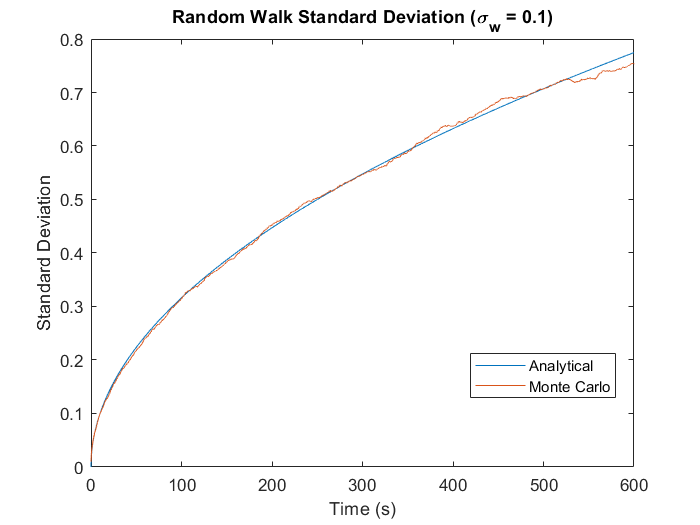


figure
plot(t,an_std_wn1)
hold on
plot(t,std_wn1)
title('Random Walk Standard Deviation (\sigma_w = 0.1)')
xlabel('Time (s)')
ylabel('Standard Deviation')
legend('Analytical','Monte Carlo','Location','best')

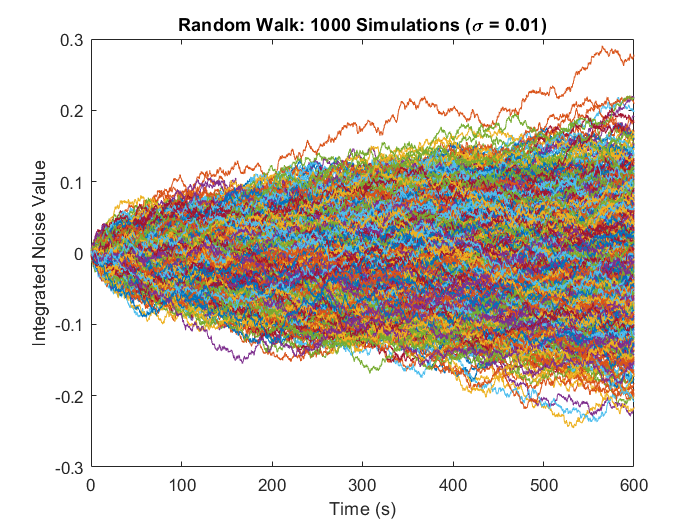


figure
plot(t,int_wn2)
title('Random Walk: 1000 Simulations (\sigma = 0.01)')
xlabel('Time (s)')
ylabel('Integrated Noise Value')

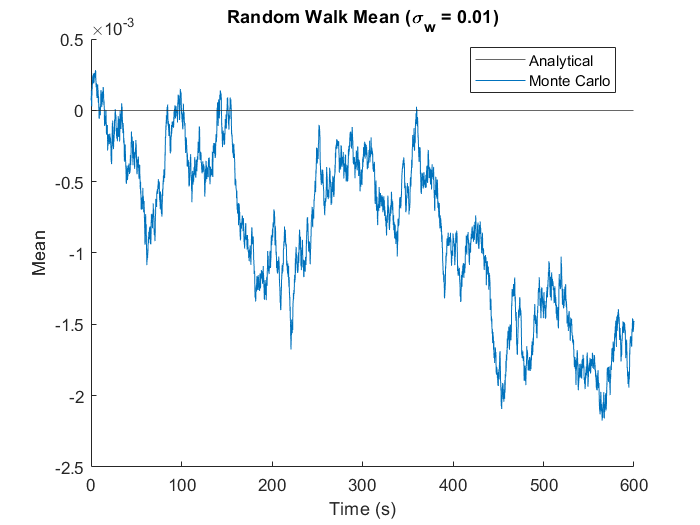


figure
yline(0)
hold on
plot(t,mean_wn2)
title('Random Walk Mean (\sigma_w = 0.01)')
xlabel('Time (s)')
ylabel('Mean')
legend('Analytical','Monte Carlo','Location','best')

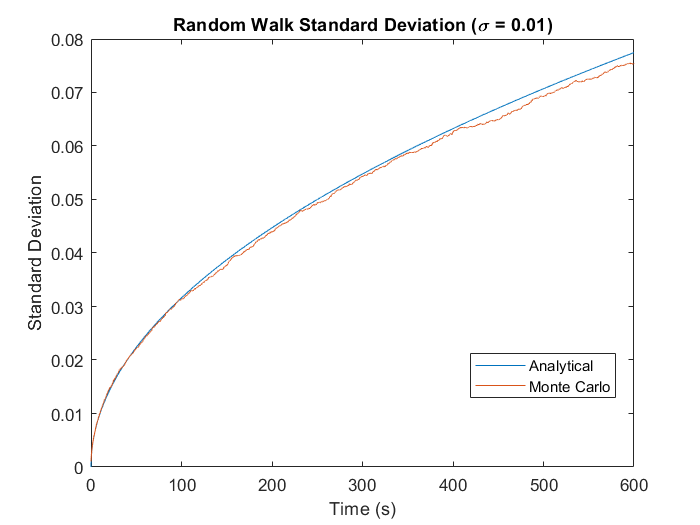


figure
plot(t,an_std_wn2)
hold on
plot(t,std_wn2)
title('Random Walk Standard Deviation (\sigma = 0.01)')
xlabel('Time (s)')
ylabel('Standard Deviation')
legend('Analytical','Monte Carlo','Location','best')


clearvars

- **Part C:**

## **Problem 2**

### Find:

- Determine the expected uncertainty for an L1-L5 ionosphere free pseudorange measurement and L2-L5 ionosphere free pseudorange. Assuming all measurements have the same accuracy (L1, L2, L5) which will provide the best ionosphere estimate?

### Solution:

- The following equation can be used to determine which dual frequency ionosphere correction has the best estimate:


$$\rho_{IF} = \frac{f_1^2}{f_1^2-f_2^2}\rho_1 - \frac{f_2^2}{f_1^2-f_2^2}\rho_2$$


            Specifically, the scaling terms (such as those in Problem 1) applied to the pseudoranges can be applied to the standard deviation of each measurement to determine which combination of L-band frequencies is the best at estimating the ionoshphere. The L1-L5 ionosphere scaling terms are as follows:


$$L1L5_1 = \frac{1575.42^2}{1575.42^2-1176.45^2} = 2.2606$$



$$L1L5_2 = \frac{1176.45^2}{1575.42^2-1176.45^2} = 1.2606$$


The L2-L5 ionosphere scaling terms are as follows:


$$L2L5_1 = \frac{1227.60^2}{1227.60^2-1176.45^2} = 12.2553$$



$$L2L5_2 = \frac{1176.45^2}{1227.60^2-1176.45^2} = 11.2553$$


Looking at these scaling factors, it is easy to see the L1-L5 combination will provide the better estimate. This is because the inclusion of the L1 frequency. The higher the frequency, the less ionosphere attenuation. However, to further prove this, the analytical equation from Problem 1 Part A can be used. The standard deviation of each measurement was assumed to be 0.5 m.


$$\sigma_{\rho IFL1L5} = \sqrt{2.2606(0.5)^2 + 1.2606(0.5)^2} = 0.9382m$$



$$\sigma_{\rho IFL2L5} = \sqrt{12.2553(0.5)^2 + 12.2553(0.5)^2} = 2.4244m$$


These standard deviations clearly show L1-L5 is the better estimate of the ionosphere.

sigma = 0.5;

% GPS L-Band Frequencies (MHz)
L1 = 1575.42;
L2 = 1227.60;
L5 = 1176.45;

L1L5(1) = ( L1^2 / (L1^2 - L5^2) );
L1L5(2) = ( L5^2 / (L1^2 - L5^2) );
L2L5(1) = ( L2^2 / (L2^2 - L5^2) );
L2L5(2) = ( L5^2 / (L2^2 - L5^2) );

sigma_L1L5 = sqrt(L1L5(1) * sigma^2 + L1L5(2) * sigma^2);
sigma_L2L5 = sqrt(L2L5(1) * sigma^2 + L2L5(2) * sigma^2);

## Problem 3

### Find:

- Show that the differential GPS problem is linear. In other words derive the following expression:


$$\Delta \rho = \left[ \matrix{uv_x & uv_y & uv_z & 1}\right]
\left[ \matrix{r_x \cr r_y \cr r_z \cr c \delta t_{ab}}\right]$$


### Solution:

- The following is the derivation of single difference differential GPS (note: vector notation $\bar{X}_{ab}$ is the vector from a to b):


$$\rho_u = r_u + c \delta t_u + I_u + T_u + \nu_u$$



$$\rho_b = r_b + c \delta t_b + I_b + T_b + \nu_b$$
    

              Assuming ionosphere and troposphere error are the same for user and base:


$$\Delta \rho_{ub} = (r_u - r_b) + (c \delta t_u - c \delta t_b)+ (\nu_u - \nu_b)$$



$$r_u = | \bar{X}^j - \bar{X}_u|$$



$$r_b = | \bar{X}^j - \bar{X}_b|$$



$$r_u - r_b = -(\bar{X}_u - \bar{X}_b) \cdot \bar{u}_u^j$$



$$r_u - r_b = -\bar{X}_{ub} \cdot \bar{u}_u^j$$



$$r_u - r_b = \bar{X}_{bu} \cdot \bar{u}_u^j = |\bar{X}_{bu}| cos(\theta)$$
 

            The difference in ranges is assumed to be $|\bar{X}_{bu}|$ because of a small angle approximation. The SV is so far from the user and base that the angle between them from the SV is approximately zero. Therefore, $\bar{X}_{bu} \cdot \bar{u}_u^j = |\bar{X}_{bu}|$because $\theta = 0$. Ignoring noise, this leads to the following formulation.


$$\Delta \rho_{ub} = \bar{X}_{bu} \cdot \bar{u}_u^j  + (c \delta t_u - c \delta t_b)$$


            which is equivalent to:


$$\Delta \rho_{ub} = \left[ \matrix{u^j_x & u^j_y & u^j_z & 1}\right]
\left[ \matrix{X_{bu,x} \cr X_{bu,y} \cr X_{bu,z} \cr c \delta t_{ub}}\right]$$


            or:


$$\Delta \rho = \left[ \matrix{uv_x & uv_y & uv_z & 1}\right]
\left[ \matrix{r_x \cr r_y \cr r_z \cr c \delta t_{ab}}\right]$$


## Problem 4

Set up your own 2D planar trilateration problem. Place the SVs at (0,300) (100,400), (700,400), and (800,300). Generate a range measurement for a base station at (400,0) and a user at (401,0).

### Find:

- **Part A: **Solve for the position of the user using 2 SVs and then 4 SVs assuming no clock errors. How does the PDOP change for the two cases?

- **Part B: **Solve for the position of the user assuming you need to solve for the user clock bias. What is the PDOP with all 4 satellites.

- **Part C: **Calculate a differential solution between the base and user using a single difference model and assuming you must solve for a clock bias between the base station and user. What is the PDOP with all 4 satellites?

- **Part D: **Calculate a differential solution between the base and user using a double difference model to remove the clock bias between the base station and user. What is the PDOP with all 4 satellites?

- **Part E: **Assuming the range error is zero mean with unit variance, what is the order of accuracy in the above 4 solution methods?

### Solution:

- **Part A: **The user position is shown below. The PDOP changes immensely as the number of measurements (SVs) increases. The PDOP using the first 2 SVs (relatively bad geometry) assuming a perfect clock is 18.0881. The PDOP using all 4 SVs assuming a perfect clock is 0.7071. This means the certainty of the estimate with 4 SVs is much greater. This is because the geometry provided by the first 2 SVs leaves a lot of ambiguity in the y-direction. Calculating the PDOP with SVs 2 and 3 reduces the PDOP to 1.5935 which is significantly less than before but still greater than the 4 SV PDOP. Once again, this is because the geometry provided by those satellites is not as good as the 4 SV case. Using SVs 3 and 4, the PDOP is 17.9891 making it very similar to the first 2 SV case.


$$2SVpos_{user} = [401, 0]$$



$$4SVpos_{user} = [401, 0]$$


svPos = [0 300;
        100 400;
        700 400;
        800 300];

base = [400 0];

user = [401 0];

clock_bias = 2;

rcvrSigma = 1;
rcvr = gnssReceiver(rcvrSigma);

rho_user = sqrt( (svPos(:,1) - user(1)).^2 +  (svPos(:,2) - user(2)).^2 );

% Part A
pc2 = rcvr.p2DPC(rho_user(1:2,:), svPos(1:2,:)');
pc4 = rcvr.p2DPC(rho_user, svPos');

pc2.PDOP = sqrt( pc2.DOP(1,1)^2 + pc2.DOP(2,2)^2 );
pc4.PDOP = sqrt( pc4.DOP(1,1)^2 + pc4.DOP(2,2)^2 );

- **Part B: **The user position is shown below. Using 4 SVs and assuming you need to solve for the user clock bias, the PDOP was 25.005. This is relatively high compared to the perfect clock results in Part A. The addition of clock bias estimation further exacerbates the ambiguity in the y-direction as proven by the y DOP value being 25 compared to 0.5 for the x DOP value. 

   
$$pos_{user} = [401, 0]$$


% Part B
rho_user = sqrt( (svPos(:,1) - user(1)).^2 +  (svPos(:,2) - user(2)).^2 ) + clock_bias;
rho_base = sqrt( (svPos(:,1) - base(1)).^2 +  (svPos(:,2) - base(2)).^2 );

cb = rcvr.p2D(rho_user, svPos');

cb.PDOP = sqrt( cb.DOP(1,1)^2 + cb.DOP(2,2)^2 );

- **Part C: **The user position is shown below. The PDOP for this case remained 25.005 because the effect of estimating the clock bias still holds as the difference between the base and user clock bias is being estimated. The benefit of single difference can't really be seen here as there is no ionosphere effect on the ranges. The reason the y position value is different is because the small angle approximation used in the single difference forumlation breaks down slightly because the SVs are relatively close to the user and base compared to those in the real world.


$$pos_{user} = [401, -0.0014]$$


% Part C
sd = rcvr.sdp2D(rho_user, rho_base, svPos', base);

sd.PDOP = sqrt( sd.DOP(1,1)^2 + sd.DOP(2,2)^2 );

- **Part D: **The user position is shown below. The PDOP for this case was 17.3807. You would initially expect it to mimic Part A and return to 0.7071. However, this is not the case because of the $\Delta$ unit vectors that exist in the $G$ matrix. There would be at least one element of the $G$ matrix that is close to zero which would create higher uncertainty because of the relatively close SV positions. 

% Part D
dd = rcvr.ddp2D(rho_user, rho_base, svPos', base);

dd.PDOP = sqrt( dd.DOP(1,1)^2 + dd.DOP(2,2)^2 );

- **Part E: **Considering the noise on the measurements doesn't effect the PDOPs, the most accurate solutions are ranked as follows (1 = most accurate):

- 4 SV Perfect Clock (Part A)

- Double Difference (Part D)

- 2 SV Perfect Clock (Part A)

- 4 SV Clock Bias & Single Difference (Parts B & C)

svPos = [0 300;
        100 400;
        700 400;
        800 300];

base = [400 0];

user = [401 0];

clock_bias = 2;

rcvrSigma = 1;
rcvr = gnssReceiver(rcvrSigma);

rho_user = sqrt( (svPos(:,1) - user(1)).^2 +  (svPos(:,2) - user(2)).^2 ) + randn;

% Part A
pc2 = rcvr.p2DPC(rho_user(1:2,:), svPos(1:2,:)');
pc4 = rcvr.p2DPC(rho_user, svPos');

pc2.PDOP = sqrt( pc2.DOP(1,1)^2 + pc2.DOP(2,2)^2 );
pc4.PDOP = sqrt( pc4.DOP(1,1)^2 + pc4.DOP(2,2)^2 );

% Part B
rho_user = sqrt( (svPos(:,1) - user(1)).^2 +  (svPos(:,2) - user(2)).^2 ) + clock_bias + randn;
rho_base = sqrt( (svPos(:,1) - base(1)).^2 +  (svPos(:,2) - base(2)).^2 );

cb = rcvr.p2D(rho_user, svPos');

cb.PDOP = sqrt( cb.DOP(1,1)^2 + cb.DOP(2,2)^2 );

% Part C
sd = rcvr.sdp2D(rho_user, rho_base, svPos', base);

sd.PDOP = sqrt( sd.DOP(1,1)^2 + sd.DOP(2,2)^2 );

% Part D
dd = rcvr.ddp2D(rho_user, rho_base, svPos', base);

dd.PDOP = sqrt( dd.DOP(1,1)^2 + dd.DOP(2,2)^2 );

## **Problem 5**

### **Find:**

- (Bonus for Undergrads/Required for Grads). Repeat problem #3 using 4 and 8 SV positions from Lab #2 (4,7,8,9,16,21,27,30). Comment on any difference or similarities with the planar problem in #3.

### Solution:

- s

## Problem 6

Chapter 2, Problem 1a and 1b for PRN #4. Repeat 1a for PRN #7.

### Find:

- **Part A: **Create the entire 1023-chip C/A code for the PRNs as a vector. Plot the first 16 and last 16 chips in the code.

- **Part B: **Create the C/A code output from time epochs 1024 to 2046. How does this compare to Part A?

### Solution:

- **Part A: **The function used to calculate the C/A code for PRN 4 and 7 was validated by checking if the hex representation of the first 16 chips of PRN 19 was E6D6. Although it is not shown here, they did match indicating the other PRNs are also correct. The plots for the first and last 16 chips of each PRN are shown below.

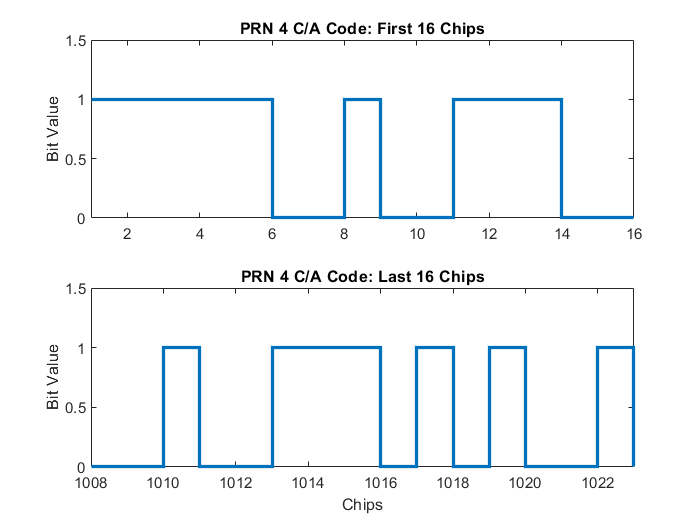

codeL = 1023;

CA4 = genCA(4, codeL);
CA7 = genCA(7, codeL);

chips = 16;

first = 1:chips;
last = codeL-(chips-1):codeL;

figure
subplot(2,1,1)
stairs(first, CA4(first), 'LineWidth', 2)
xlim([first(1) first(end)])
ylim([0 1.5])
title('PRN 4 C/A Code: First 16 Chips')
ylabel('Bit Value')

subplot(2,1,2)
stairs(last, CA4(last), 'LineWidth', 2)
xlim([last(1) last(end)])
ylim([0 1.5])
title('PRN 4 C/A Code: Last 16 Chips')
xlabel('Chips')
ylabel('Bit Value')

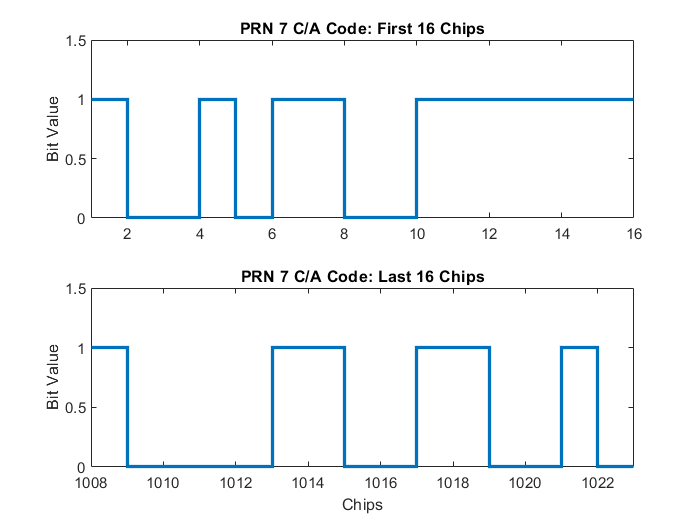


figure
subplot(2,1,1)
stairs(first, CA7(first), 'LineWidth', 2)
xlim([first(1) first(end)])
ylim([0 1.5])
title('PRN 7 C/A Code: First 16 Chips')
ylabel('Bit Value')

subplot(2,1,2)
stairs(last, CA7(last), 'LineWidth', 2)
xlim([last(1) last(end)])
ylim([0 1.5])
title('PRN 7 C/A Code: Last 16 Chips')
xlabel('Chips')
ylabel('Bit Value')


clearvars

- **Part B: **The following plots for time epochs (total chips from start of code generation) 1024 to 2046 are shown below. The exactly replicate those shown in PArt A meaning the code repeates every 1023 epochs or chips.

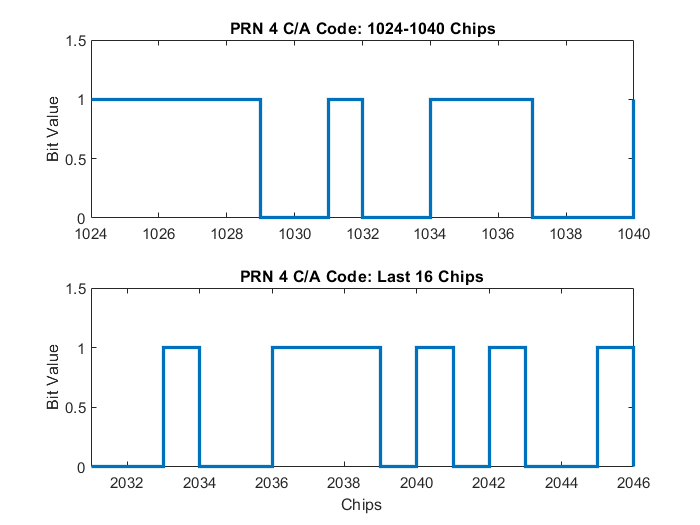

codeL = 2046;

CA4 = genCA(4, codeL);
CA7 = genCA(7, codeL);

chips = 16;

first = 1024:1040;
last = codeL-(chips-1):codeL;

figure
subplot(2,1,1)
stairs(first, CA4(first), 'LineWidth', 2)
xlim([first(1) first(end)])
ylim([0 1.5])
title('PRN 4 C/A Code: 1024-1040 Chips')
ylabel('Bit Value')

subplot(2,1,2)
stairs(last, CA4(last), 'LineWidth', 2)
xlim([last(1) last(end)])
ylim([0 1.5])
title('PRN 4 C/A Code: Last 16 Chips')
xlabel('Chips')
ylabel('Bit Value')

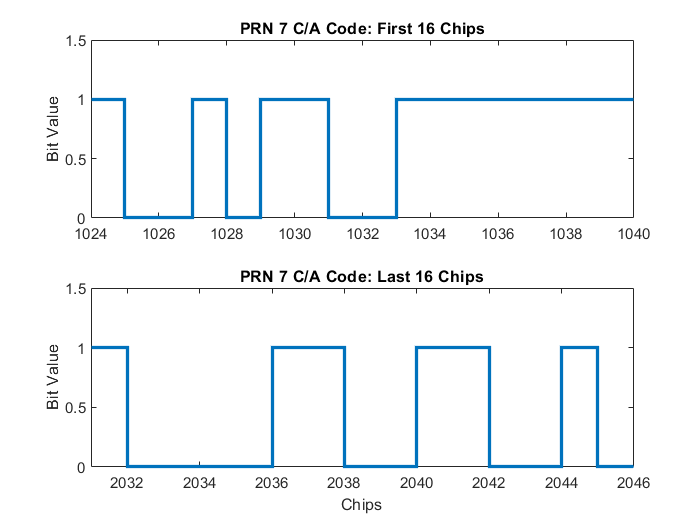


figure
subplot(2,1,1)
stairs(first, CA7(first), 'LineWidth', 2)
xlim([first(1) first(end)])
ylim([0 1.5])
title('PRN 7 C/A Code: First 16 Chips')
ylabel('Bit Value')

subplot(2,1,2)
stairs(last, CA7(last), 'LineWidth', 2)
xlim([last(1) last(end)])
ylim([0 1.5])
title('PRN 7 C/A Code: Last 16 Chips')
xlabel('Chips')
ylabel('Bit Value')


clearvars

## Problem 7

Using your PRN sequence for PRN 4 and 7, repeat problem #2 from HW#1. Compare the results to the results for your made up sequence.

### Find:

- **Part A: **Plot the histogram on each sequence.

- **Part B: **Plot the spectral analysis on each sequence.

- **Part C: **Plot the autocorrelation each sequence with itself (i.e. a sequence delay cross correlation).

- **Part D: **Plot the cross autocorrelation between the two sequences.

### Solution:

- **Part A: **The following plots show the histograms of PRN 4 and 7 for a code length of 1023 chips. The 0 chips were converted to -1 values to be used in Problem 8. The results are essentially identical to the made up sequence from HW1. This demonstrates the C/A code posseses the same qualities as a completely random sequence.

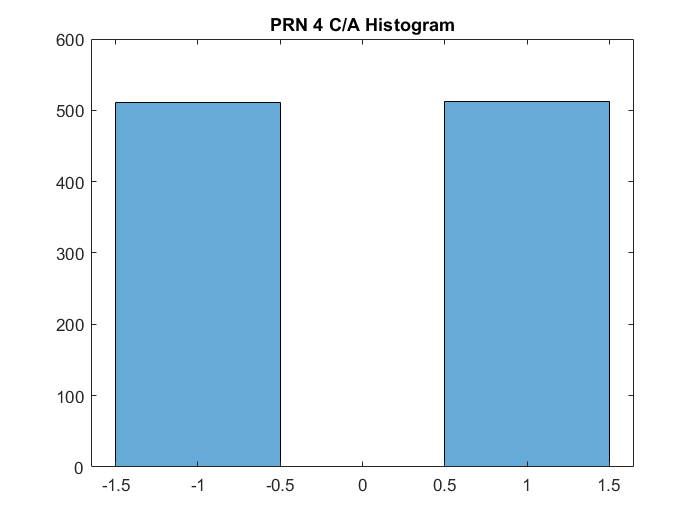

codeL = 1023;

CA4 = genCA(4, codeL);
CA7 = genCA(7, codeL);

idx4 = CA4 == 0;
idx7 = CA7 == 0;

CA4(idx4) = -1;
CA7(idx7) = -1;

figure
histogram(CA4)
title('PRN 4 C/A Histogram')

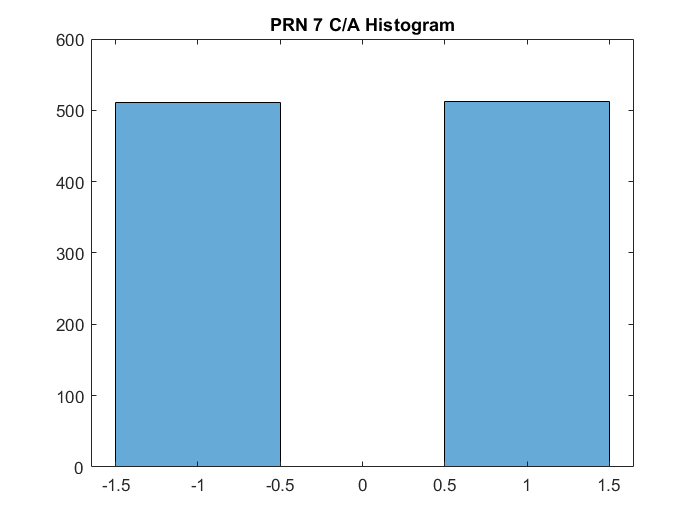

figure
histogram(CA7)
title('PRN 7 C/A Histogram')

- **Part B: **The following plots show the Power Spectral Density for PRN 4 and 7. Once again, they look identical to the PSDs from the sequences generated in HW1. This further solidifies the claim that the PRN C/A code behaves the same way as a completely random sequence. 

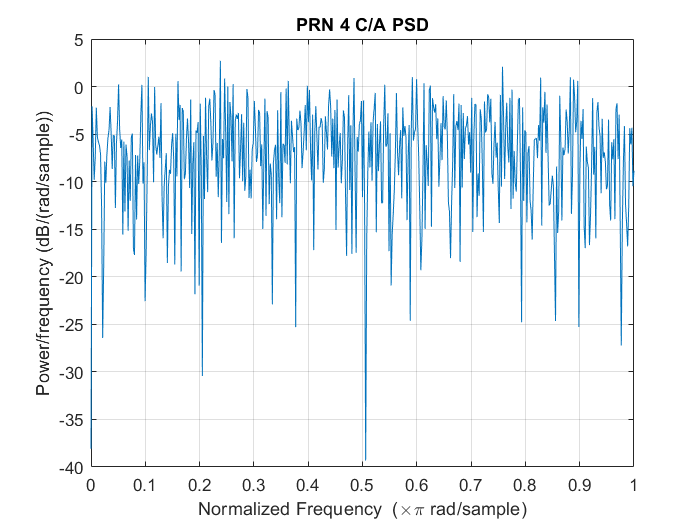

figure
periodogram(CA4)
title('PRN 4 C/A PSD')

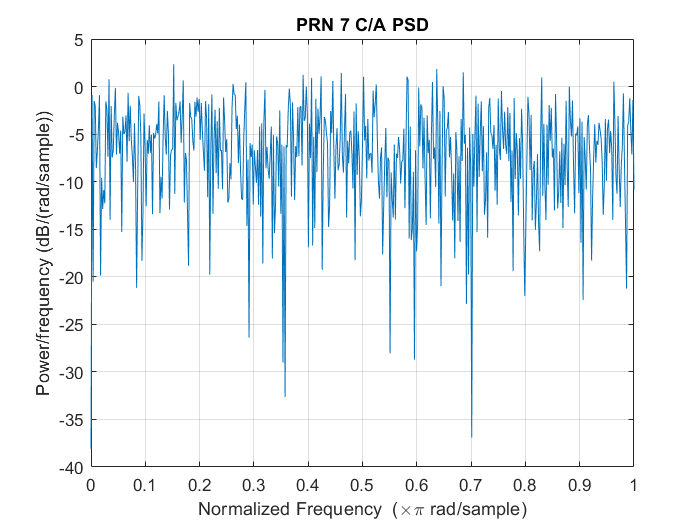

figure
periodogram(CA7)
title('PRN 7 C/A PSD')

- **Part C: **The following plots show the autocorrelation for PRN 4 and 7. Like before, they look the same as the sequences generated in HW1. They are only correlated with themselves at one point in time (when aligned) which means they possess the same qualities as a random sequence.

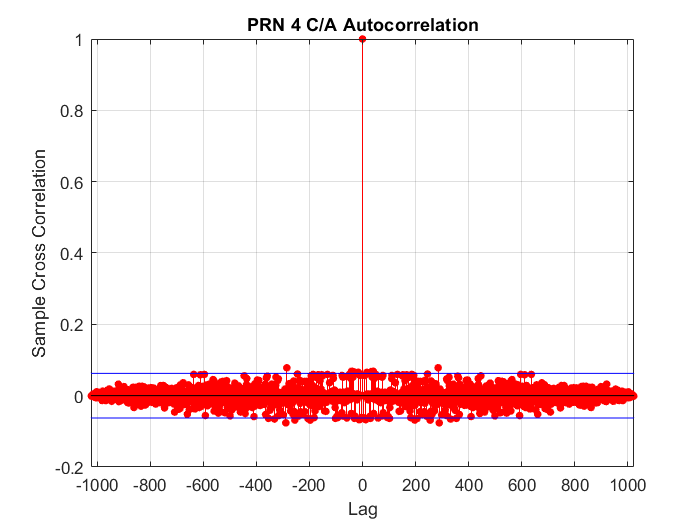

figure
crosscorr(CA4, CA4, 'NumLags', codeL-1)
title('PRN 4 C/A Autocorrelation')
xlim([-codeL codeL])

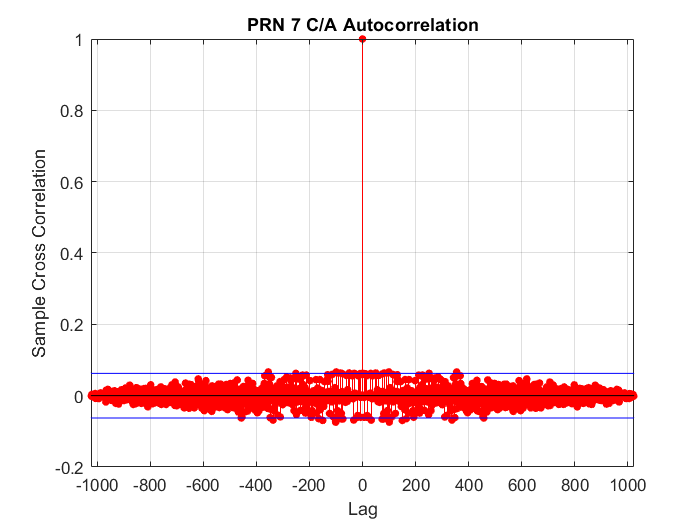

figure
crosscorr(CA7, CA7,  'NumLags', codeL-1)
title('PRN 7 C/A Autocorrelation')
xlim([-codeL codeL])

- **Part D: **The following plot shows the cross correlation for PRN 4 and 7. As in HW1, there is no definite correlation at any point shifted in time meaning the two are always distinguishable. Once again, another property of random sequences.

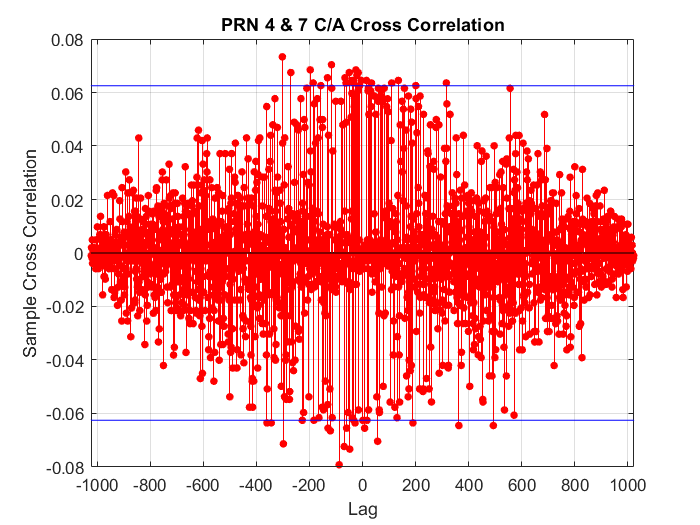

figure
crosscorr(CA4, CA7, 'NumLags', codeL-1)
title('PRN 4 & 7 C/A Cross Correlation')
xlim([-codeL codeL])

## **Problem 8**

### **Find:**

- Take your C/A code from problem above (i.e. PRN #4 and #7) and multiply it times the L1 Carrier (your C/A code must be in the form -1 and +1). Perform a spectral analysis (magnitude) on the resultant signal. You will need to make sure to “hold” your C/A code bits for the correct length of time (I suggest using a sample rate 10x the L1 carrier frequency – meaning each chip of the C/A code will be used for 10 samples of the sine wave).

### Solution:

- The following plots show the PSD of the resultant signals. The peak power is centered around the L1 carrier frequency for both PRNs as expected. The narrow band about the L1 frequency shows how multiple GPS signals in the L-band can be observed by a receiver. The modulation because of the code is also evident.

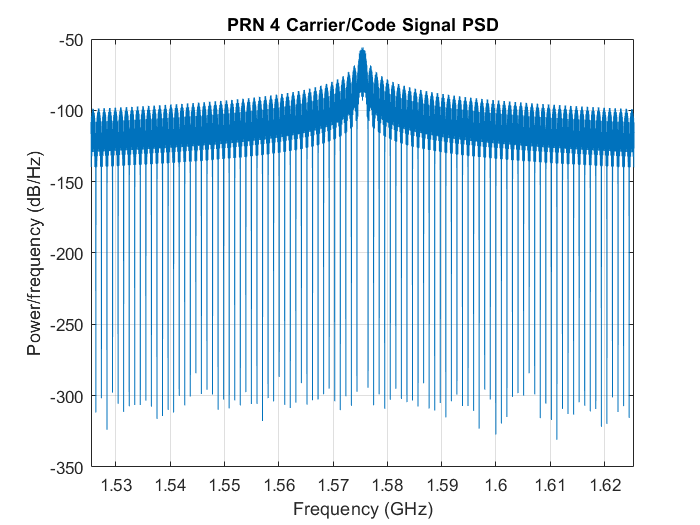

codeL = 1023;

CA4 = genCA(4, codeL);
CA7 = genCA(7, codeL);

idx4 = find(CA4 == 0);
idx7 = find(CA7 == 0);

CA4(idx4) = -1;
CA7(idx7) = -1;

CA4 = reshape(repmat(CA4',10*1540,1),1,[]);
CA7 = reshape(repmat(CA7',10*1540,1),1,[]);

fL1 = 1575.42e6; % L1 frequency (Hz)

fs = fL1*10;

dt = 1/fs;

t = dt:dt:0.001;

L1car = sin((fL1*2*pi).*t);

L1sig4 = L1car .* CA4;

L1sig7 = L1car .* CA7;

figure
periodogram(L1sig4,[],length(L1sig4),fs)
title('PRN 4 Carrier/Code Signal PSD')
xlim([1.57542-0.05 1.57542+0.05])

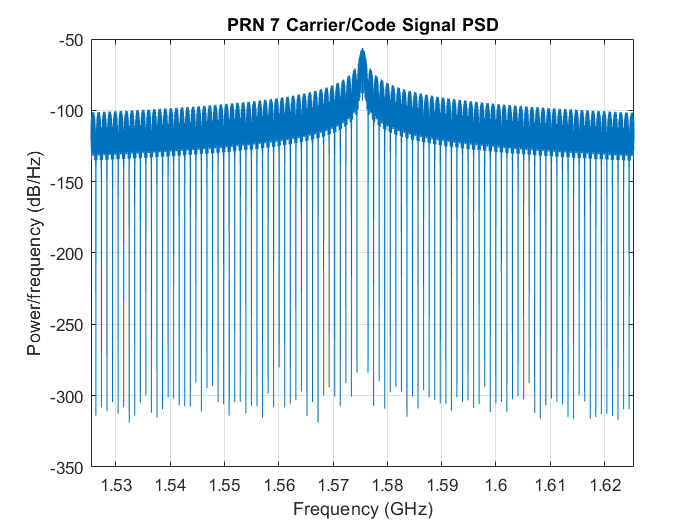


figure
periodogram(L1sig7,[],length(L1sig7),fs)
title('PRN 7 Carrier/Code Signal PSD')
xlim([1.57542-0.05 1.57542+0.05])